# Vision: YOLO

In this notebook we will learn to adjust our gazebo scenes, collect images, label them, train our YOLO detector, and then leverage it. 

# 0. Connect to the Simulation

We will open up the UR simulation in gazebo.

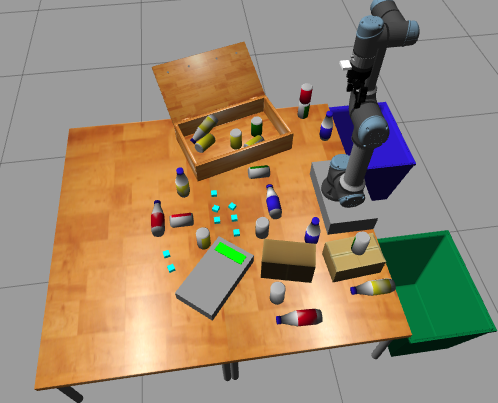

## 0.1 Run your Virtual Machine

To this end, you will need to run your virtual machine and start the armgazebo container. 

## 0.2 Run your Container

Remember to call run.bash from inside src/arm_gazebo/docker:

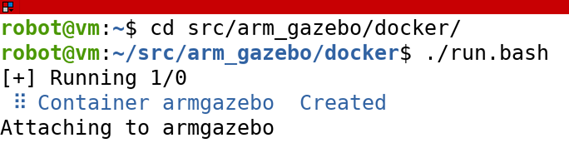

Also retrieve your hostname via command: hostname -I

## 0.3 Simplify your Scence

To start, let's simplify our scene, only keeping one object on our table. 

### 0.3.1 Changing the Staging File

- Open a terminator terminal and open tmux inside the armgazebo container:

            

- Change to the `src/armgazebo/config` folder:

- 

- Open the ARM0.txt file using the text editor nano:

-  

- Modify your file to only keep one object similar to the image below: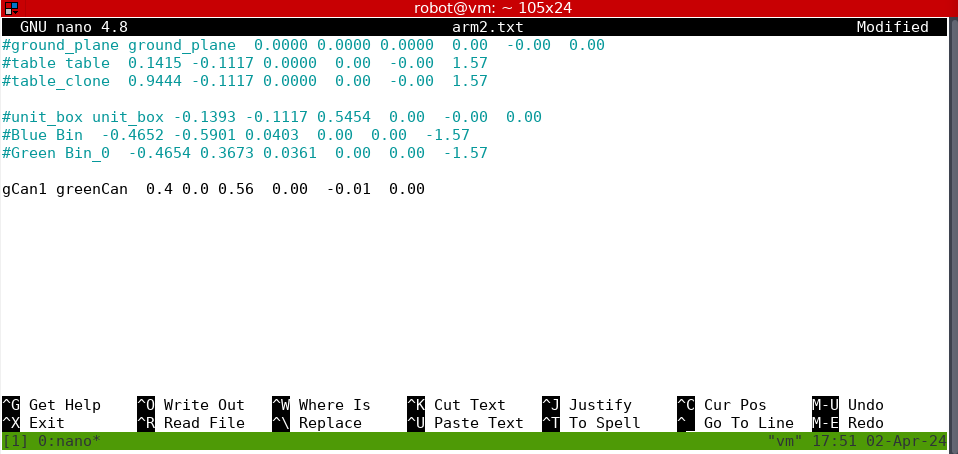

- Press Ctrl+o to save. At the bottom of the screen, Nano will prompt you to confirm the file name. Change the name to arm1.txt and press Enter. Confirm any other prompts.

### 0.3.2 Loading a new scene

Once we have this file, we can run a script to load gazebo with this staging file.

- Change directories from the config folder to the scripts folder: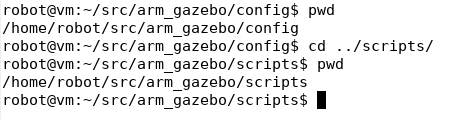

- If you call `ls`, you will see there are 3 executable scripts in this folder:

- You can call `reset_world.py` and pass it the path to your arm1.txt file to reset gazebo. Remember executables are run with a `./` and the path is one folder up and into config:

- After running it, you will see the terminal indicating objects are being deleted (you will see them disappear in gazebo) and finally **spawning** the objects in the new file: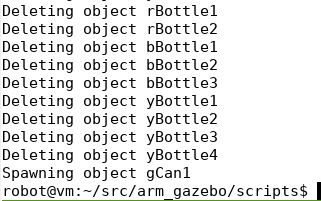  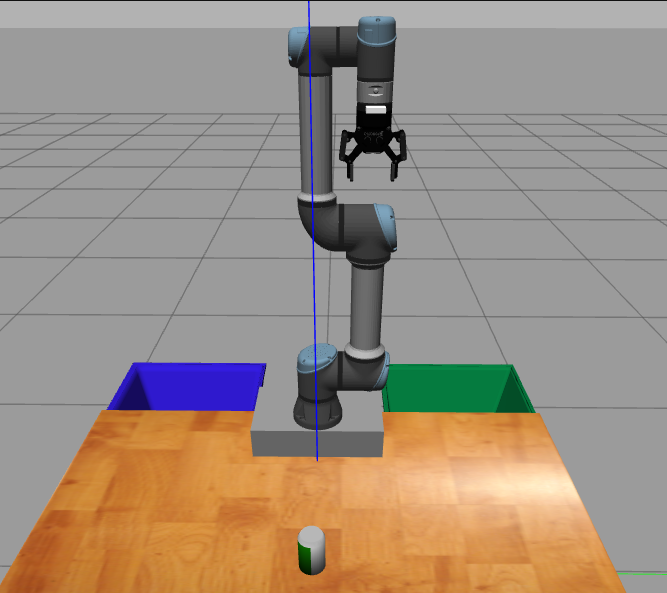

- We will start collecting a diverse set of images for one set at a time. Later, you will come back and change arm1.txt with {name,object} pairs like: 

            {`rCan1,redCan},{bBottle1,blueBottle},{pouch1,pouch}`

`      but keep the pose exactly the same.`

# 1. Data Collection

From our master ros_matlab code, change directory to the _vision/yolo folder.

The script `collect_yolo_data.m` selects a model and then calls `collect_obj_images. `The later will move the arm in concentric circles around the object taking pictures from different angles. There are 3 main parameters: 

- a rotation offset (determines the number of points to visit around the circle), 

- a linear offset (the distance from the center of the object at which to go around the circle), and 

- the number of iterations (the number of concentric circles at increasing offsets to execute).

#### Noise

Noise is injected into both the rotational and linear offsets to create different trajectories and as a result sets of images. This increased diversity should help with better training data.

#### **Caveats**

It is possible, that some images may not contain a can. That is, where the noise might have driven the arm a bit too far away from the can. These images will be labeled as null.

#### Image Names

The resulting images will be saved in a single image structure that will be saved in a data folder inside yolo. The name of the file uses the input model name to encode a name with the following pattern:

    color_objectType_yyyymmdd_HHMMSS.mat

## 1.1 Merging multiple Images

If you have multiple image structures, you can merge them with the `merge_img_structures.m` script/function. All your existing image structurse will be the input to the function, set the output as **yoloTrainingData **and save it also as 

Each time will be tasked to work with different objects. When you finish and obtain your final image structure, upload it to the following google drive link. We will use it to train the detector: [https://drive.google.com/drive/folders/1VQpBL9mi5HoMyaXcK60UaEWurd0Bp731?usp=sharing](https://drive.google.com/drive/folders/1VQpBL9mi5HoMyaXcK60UaEWurd0Bp731?usp=sharing) 

Note, that in this setup, we only have objects over the table. We should set up scenes where the objects are on top of boxes or other settings to get a more diverse set of images. 

# 2. Training the Yolo Network 

## 2.1 Labeling Images

All the images we have taken, need to be labeled using the [Image Labeler](docid:vision_ref.mw_96fe579b-b33c-4798-a463-6fdeee7cd214) app, creating the training dataset for the YOLO v2 detection model. The app provides an easy way to interactively create a variety of shapes to mark as region of interest (ROI) labels

Generally we will:

- Load new or partially labeled images or a saved project

- Create a datastore for images

- Define labels using the app or programmatically via the method [`labelDefinitionCreator`](https://www.mathworks.com/help/vision/ref/labeldefinitioncreator.html)

- Create ROI

- Create Labels

- Export the labled images as a groundTurth or tained_data table to train the network.

- Save the session as an individual/team project. 

For additional resources on Image Labeler see:

- [https://www.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html](https://www.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html) 

- [https://www.mathworks.com/help/vision/ug/getting-started-with-yolo-v4.html](https://www.mathworks.com/help/vision/ug/getting-started-with-yolo-v4.html) 

- [https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab/](https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab/) 

In this step we will draw bounding boxes around images and provide labels. 

**Step 1: Labeling Images in the Image Labeler App**

- **Open the Image Labeler App**: In MATLAB, you can open the Image Labeler app by typing `imageLabeler` in the Command Window.

- **Load Your Dataset**: Import the images you want to label into the app. You can do this by choosing "Add Images" and selecting the images from your computer or workspace.

- **Define Label Categories**: Create label categories for your objects, such as cans, bottles, and pouches. Additionally, define bounding box labels for identifying the position of each object within the images.

- **Label Your Images**: Manually draw bounding boxes around each object in your images and assign them to the correct category (can, bottle, or pouch).

We will end with a two-column table. The first column contain the image file paths and the second column contain the bounding boxes.

## 2.2 Preprocessing Data

Once you have finished labeling your images with bounding boxes and labels, you can export that dataset to file/workspace. Let's call it arm_training_data. 

trainingData = arm_training_data_2; % Class table

**Data Analysis**

Display the data set summary.

summary(trainingData)

Variables:

    imageFilename: 295×1 cell array of character vectors

    vehicle: 295×1 cell



Combine all the ground truth boxes into one array.

first_obj_box = vertcat(trainingData(:,2); % TODO may neeed to create boxes for each object

Plot the box area versus the box aspect ratio.

aspectRatio = first_obj_box(:,3) ./ first_obj_box(:,4);
area = prod(first_obj_box(:,3:4),2);

figure
scatter(area,aspectRatio)
xlabel("Box Area")
ylabel("Aspect Ratio (width/height)");
title("Box Area vs. Aspect Ratio")

Randomly shuffle data for training. Split the dataset into training, validation, and test sets. Select 60%  of the data for training, 10% for validation, and the rest for testing  the trained detector.

rng(0);
shuffledIndices = randperm(height(trainingData)); % Get table height and permute entries

idx = floor(0.6 * length(shuffledIndices) );

% Training Data
trainingIdx = 1:idx;
trainingDataTbl = trainingData(shuffledIndices(trainingIdx),:);

% Validation Data
validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = trainingData(shuffledIndices(validationIdx),:);

% Test Data
testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = trainingData(shuffledIndices(testIdx),:);

#### Datastores

Datastores in MATLAB are a powerful and flexible way to manage large  collections of data, particularly when the data is too large to fit into memory all at once. A datastore is an object that enables you to read  and process data in chunks, making it possible to work efficiently with  big data. The concept is crucial for data analytics, machine learning,  and any application requiring the manipulation of large datasets. 

MATLAB datastores can handle a variety of data formats, including but  not limited to text files (CSV, TSV), images, spreadsheets, and binary  files. Specialized datastores are available for specific data types,  like `ImageDatastore` for image data, `TabularTextDatastore` for tabular text data, etc.

Use `imageDatastore` and `boxLabelDatastore` to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl.imageFilename);
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:end));

imdsValidation  = imageDatastore(validationDataTbl.imageFilename);
bldsValidation  = boxLabelDatastore(validationDataTbl(:,2:end));

imdsTest  = imageDatastore(testDataTbl.imageFilename);
bldsTest  = boxLabelDatastore(testDataTbl(:,2:end));

Combine image and box label datastores.

trainingData    = combine(imdsTrain,bldsTrain);
validationData  = combine(imdsValidation,bldsValidation);
testData        = combine(imdsTest,bldsTest);

#### Validate Data

Use `validateInputData` to detect invalid images, bounding boxes or labels when the data set contains one or more of the following:

- Samples with invalid image format or NaN values

- Bounding boxes containing zeros/NaN values/Inf values/empty

- Missing or non-categorical labels

The values of the bounding boxes must be finite positive integers and must  not be NaN. The height and the width of the bounding box values must be  positive and lie within the image boundary.

validateInputData(trainingData);
validateInputData(validationData);
validateInputData(testData);

For debugging purposes, display one of the training images and box labels

data = read(trainingData);
I = data{1};

bbox = data{2};
annotatedImage = insertShape(I,"Rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

Reset your training data:

reset(trainingData);

## 2.3. Create a YOLO v4 Object Detector Network

To create the YOLO v4 object detector by using the `yolov4ObjectDetector` function. We will first have to specify the following information:

- image input size [MxNx3]

- class names {class1, class2, classN}

- estimated anchor boxes (se below)

- the name of a pretrained YOLO v4 detection network: "tiny-yolov4-coco" or "csp-darknet53-coco".

### 2.3.1 Set the network input size:

ROS is outputing square images of size [416,416,3].

inputSize = [416 416 3];

### 2.3.2 Set the classes labels in a cell array. 

Class labels will need to match the ground truth labels produced during the labeling. The process may change as you do more sophisticated training.

classes = {'red_can','red_bottle'}; % cans-rgy | bottles-rby; pouches; wcase, box1, box2? At least 7 classes, max 10.

### 2.3.3 Specify Achor Boxes

Assume that you specify four anchor boxes for each detection head (there are 3 in yolov4):

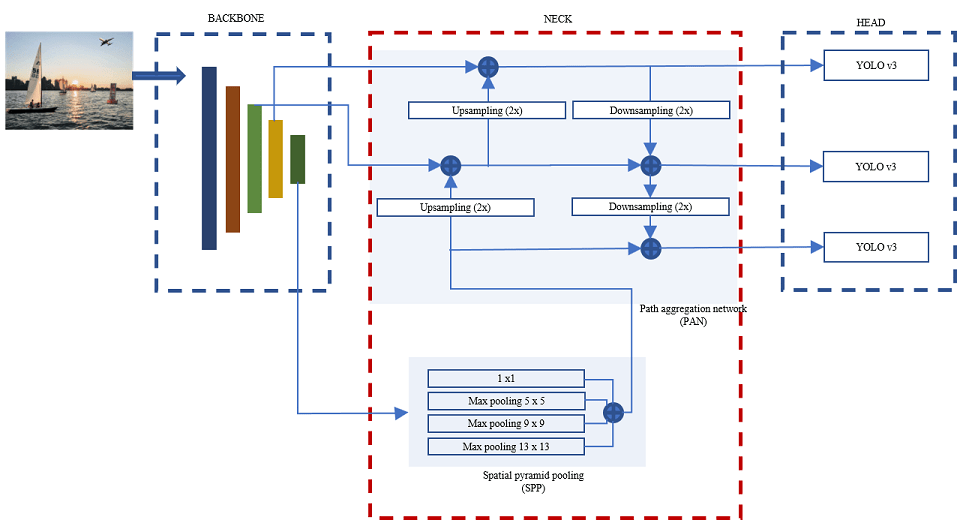

The position of an anchor box is determined by mapping the location of the network output back to the input image. The process is replicated for every network output. The result produces a set of tiled anchor boxes across the entire image. Each anchor box represents a specific prediction of a class. For example, there are two anchor boxes to make two predictions per location in the image below.

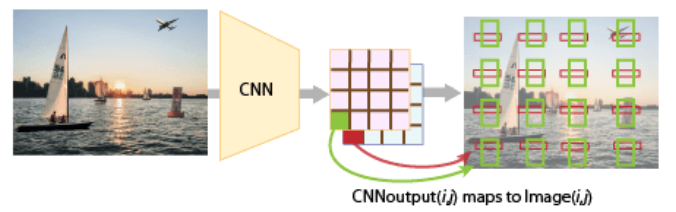

Each anchor box is tiled across the image. The number of network outputs equals the number of tiled anchor boxes. The network produces predictions for all outputs. Then, the total number of anchor boxes that you use for training the network must be twelve. You can use the [`estimateAnchorBoxes`](https://www.mathworks.com/help/vision/ref/estimateanchorboxes.html) function to automatically estimate the anchor boxes for your specified training data.

**Purpose of Anchor Boxes**

Anchor boxes are predefined bounding boxes that have been designed to predict the shapes and sizes of objects in an image. Their main purposes are:

- **To Predict Multiple Objects per Grid Cell**: Originally, YOLO divides the image into a grid, and each grid cell was responsible for predicting only one object. This could lead to problems when multiple objects fell within a single cell. Anchor boxes allow each grid cell to predict multiple objects by associating each object with the best matching anchor box.

- **To Handle Different Object Shapes and Sizes**: By defining anchor boxes of various aspect ratios and sizes, YOLO can more accurately predict objects that vary significantly in shape and size, from tall and narrow to short and wide.

**Determination Before Training**

- **Predefined Sizes**: Anchor boxes are predefined and fixed in number. Their sizes and ratios are typically chosen based on common shapes and sizes of objects in the training dataset. Sometimes, k-means clustering on the training set bounding boxes is used to automatically determine the most representative anchor boxes.

- **Used During Training and Inference**: The model learns to adjust these anchor boxes to match the actual objects during training. For each anchor box, the model predicts adjustments to the box's position and dimensions, as well as the object class.

**Spacing and Stride**

- **Grid and Stride**: The image is divided into a grid (e.g., 13x13, 26x26), and each grid cell is responsible for predicting objects whose center falls within the cell. The stride refers to the step in pixels between grid cells in the original image. For example, if the input image is 416x416 pixels and the grid size is 13x13, the stride is 32 pixels (416/13).

- **Scale-Specific Anchors**: YOLOv3 and later versions use multiple scales to detect objects. Smaller anchor boxes are used at higher resolutions (fine-grained features) to detect smaller objects, and larger anchor boxes are used at lower resolutions (coarse features) to detect larger objects. This multiscale approach is designed to improve the detection of objects of varying sizes.

**How They Work**

During training and inference:

- Each grid cell uses its anchor boxes to predict bounding boxes for objects. The model outputs adjustments to the anchor boxes (e.g., scale and aspect ratio adjustments) to better fit the actual objects.

- Each prediction includes confidence scores for objectness (whether an object is present) and class probabilities.

- The "best matching" anchor box for a given object during training is usually the one with the highest IoU (Intersection over Union) with the ground truth bounding box.

**Summary**

To summarize, anchor boxes in YOLO:

- Allow the detection of multiple objects per grid cell.

- Enable the model to handle objects of various shapes and sizes efficiently.

- Require predefinition based on the dataset and are integral during both training and inference for predicting object bounding boxes.

#### Estimate the Number of Anchor Boxes You Need

Use the [`estimateAnchorBoxes`](https://www.mathworks.com/help/vision/ref/estimateanchorboxes.html) function to estimate anchor boxes based on the size of objects in the  training data. To account for the resizing of the images prior to  training, resize the training data for estimating anchor boxes. Use the `transform` function to preprocess the training data, then define the number of  anchor boxes and estimate the anchor boxes. Resize the training data to  the input size of the network by using the `preprocessData` helper function.

rng("default")
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 6;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);

The mean IoU value greater than 0.5 ensures that the anchor boxes overlap well with the boxes in the training data.

Increasing the number of anchors can improve the mean IoU measure. However, using more anchor boxes in an object detector can also increase the computation cost and lead to overfitting, which results in poor detector performance.

Sweep over a range of values and plot the mean IoU versus number of anchor boxes to measure the trade-off between number of anchors and mean IoU.

maxNumAnchors = 15;
meanIoU         = zeros([maxNumAnchors,1]);
anchorBoxes     = cell(maxNumAnchors, 1);
for k = 1:maxNumAnchors
    % Estimate anchors and mean IoU.
    [anchorBoxes{k},meanIoU(k)] = estimateAnchorBoxes(trainingDataForEstimation,k);    
end

figure
plot(1:maxNumAnchors,meanIoU,'-o')
ylabel("Mean IoU")
xlabel("Number of Anchors")
title("Number of Anchors vs. Mean IoU")

Analyze your data and try to find a value that gives you the greatest gain without overfitting

% best_num_anchors = k; % Set the right k here. Make it divisible by 3.
% anchors = anchorBoxes{best_num_anchors}; 

Specify the `anchorBoxes` for each detection head based on the feature map size. Use larger anchors at lower scale  and smaller anchors at higher scale. To do so, sort anchors by area, in  descending order, and assign the first three to the first detection head and the last three to the second detection head.

area = anchors(:,1).*anchors(:,2); % anchors consists of a [best_num_anchors x 2] matrix
[~,idx] = sort(area,"descend");
sortedAnchors = anchors(idx,:)

#### Set anchorBoxes

There are three detection heads in the YOLO v4 network, so make three sets of best_num_anchors/3 anchor boxes each.

thresh = round(best_num_anchors/3);
anchorBoxes = {sortedAnchors( 1             :thresh,     :)...
               sortedAnchors( (thresh+1)    :(2*thresh), :)...
               sortedAnchors( ((2*thresh)+1):(3*thresh), :)};

#### 2.3.4 Instantiate a YOLO v4 object detection network

Now that we have:

- input size

- class names

- estimated anchor boxes.

We will just provide the name of the pretrained YOLO v4 detection network ("tiny-yolov4-coco" or "csp-darknet53-coco"). 

Before you complete this step, you will need to install an additional ComputerVisionToolbox required by Matlab for this newer model.As you try to run the command, matlab will prompt you.

pretrained_net = "csp-darknet53-coco"; % Or "tiny-yolov4-coco"
detector = yolov4ObjectDetector(pretrained_net,className,anchorBoxes,InputSize=inputSize);

Inspect the properties of the detector.

detector

## 2.3.5 Training Data Augmentation

This is an optional setp but data augmentation improves training accuracy. Use the `transform` function to apply custom data augmentations to the training data. The `augmentData` helper function applies the following augmentations to the input data:

- Color jitter augmentation in HSV space

- Random horizontal flip

- Random scaling by 10 percent

Note that data augmentation is not applied to the test and validation data.  Ideally, test and validation data should be representative of the  original data and is left unmodified for unbiased evaluation.

augmentedTrainingData = transform(trainingData,@augmentData);

Read and display samples of augmented training data.

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,BorderSize=10)

#### 2.3.6 Train the YOLO v4 Detector

Use `trainingOptions` to specify network  training options:

- Gradient descent technique: Adam 

- MaxEpochs: 80 

- Learning rate 0.001. 

- To train with lowest validation loss set `OutputNetwork` = `"best-validation-loss"`. 

- `ValidationData` to the validation data

- `ValidationFrequency` to 1000 (reduce freq to validate more often, increase training time).

- Use `ExecutionEnvironment` to determine what hardware resources will be used to train the network. The default value for `ExecutionEnvironment` is "`auto"`, which selects a GPU if it is available, and otherwise selects the CPU. Set `CheckpointPath` to a temporary location to enable the saving of partially trained  detectors during the training process. If training is interrupted, for  instance by a power outage or system failure, you can resume training  from the saved checkpoint. 

options = trainingOptions("adam", ...
                          GradientDecayFactor           =0.9, ...
                          SquaredGradientDecayFactor    =0.999, ...
                          InitialLearnRate              =0.001, ...
                          LearnRateSchedule             ="none", ...
                          MiniBatchSize                 =4, ...
                          L2Regularization              =0.0005, ...
                          MaxEpochs                     =80, ...
                          DispatchInBackground          =true, ...
                          ResetInputNormalization       =true, ...
                          Shuffle                       ="every-epoch", ...
                          VerboseFrequency              =20, ...
                          ValidationFrequency           =1000, ...
                          CheckpointPath                =tempdir, ...
                          ValidationData                =validationData, ...
                          OutputNetwork                 ="best-validation-loss",...
                          ExecutionEnvironment          = "auto"...
                          );

**Train YOLO v4 Object Detector**

Use the `trainYOLOv4ObjectDetector` function to train YOLO v4 object detector. This example is run on an  NVIDIA™ RTX A5000 with 24 GB of memory. Training this network took  approximately 33 minutes using this setup. The training time will vary  depending on the hardware you use. Instead of training the network, you  can also use a pretrained YOLO v4 object detector in the Computer Vision Toolbox™.

Download the pretrained detector by using the `downloadPretrainedYOLOv4Detector` helper function. To train the detector on the augmented training data, set the `doTraining` value to `true`.

doTraining = false;
if doTraining       
    % Train the YOLO v4 detector.
    [detector,info] = trainYOLOv4ObjectDetector(augmentedTrainingData,detector,options);
else
    % Load pretrained detector for the example.
    detector = downloadPretrainedYOLOv4Detector();
end

# 3. Test Detector

Sanity Check: let's see if we get expected results on a single image. 

We can do that by:

- Load a sample image

- Call detect with detector and image

- Draw bounding boxes via `insertObjectAnnotation` and passing bboxes/labels

- Display the annotated image 

img = imread("allObj.png");
[bboxes,scores,labels] = detect(detector,img);

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure, imshow(detectedImg)

## **3.1 Evaluate Detector Using Test Set**

Before we use our detector in our simulation, we must evaluate how good the detector is. To this end, we will measure its performance based on our testing data.  

[`evaluateObjectDetection`](https://www.mathworks.com/help/vision/ref/evaluateobjectdetection.html) is a method that will compute average precision information. Precision indicates correct classifications in addition to recall, which indicates the ability of the detector to find all relevant objects (see our yolo intro presentation for more on this). 

To evaluate performance, we will set a threshold for the probabiliy class confidence. A higher threshold will result in fewer detections, but those detections are more likely to be accurate. Conversely, a lower threshold allows  for more detections but includes more false positives. 

detectionResults = detect(detector,testData,Threshold=0.01);

Evaluate the object detector using average precision metric.

metrics = evaluateObjectDetection(detectionResults,testData);
classID = 1;
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};

The precision-recall (PR) curve highlights how precise a detector is at  varying levels of recall. The ideal precision is 1 at all recall levels. The use of more data can help improve the average precision but might  require more training time. Plot the PR curve.

figure
plot(recall,precision)
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",metrics.ClassMetrics.mAP(classID)))

# 4. Online Inference

Now it is time to check in our environment. 

The trained model is deployed for online inference on the single image acquired by the on-board camera when the robot is in the home position. The [`detect`](docid:vision_ref.mw_9aaec1f6-72d8-4537-9ba6-79ac24fa5d0b) function returns the image position of the bounding boxes of the detected objects, along with their classes, that is then used to find the position of the center of the top part of the objects. Using a simple camera projection approach, assuming the height of the objects is known, the object position is projected into the world and finally used as reference position for picking the object. The class associated with the bounding boxes decides which bin to place the object. 

Coming soon...